%Definicja zmiennych symbolicznych i stalych

clc; clear; close all;
syms x(t) y(t) a(t) f1(t) f2(t)...
    v_x v_y omega_a  omega_f1 omega_f2...
    x_c1 x_c2 y_c1 y_c2...
    v_xc1 v_xc2 v_yc1 v_yc2 ...
    xc1_dot xc2_dot yc1_dot yc2_dot 

m = 11.53; %kg - masa rynny
mw = 3.86; %kg - masa wibratora
len = 0.5; %m - 1/2 odleglosc miedzy sprezynami
hgt = 0.135; %m - odleglosc miedzy srodkiem masy a dolem rynny
kx = 628.4; %N/m - stala sprezystosci w x
ky = 3706; %N/m - stala sprezystosci w y
bx = 0.0239; %N/(m/s)tlumienie w x
by = 0.0027; %N/(m/s) tlumienie w y
I = 5; %kgm^2 moment bezwladnosci rynny
Iw = 3; %kgm^2 moment bezwlasnosci wibratora
e = 0.02; %m - odleglosc srodka ciezkosci od osi obrotu wibratora
g = 9.81; %ms^-2 - stala grawitacyjna
OC = 0.22; %odleglosc od srodka masy rynny do osi obrotu wibratora

%Polozenie i predkosc osi obrotu wibratorow

xc1 = -OC*cos((pi/3)-a)-e*cos(f1)+x; %przemieszczenie punktu c1 w osi x
yc1 = -OC*sin((pi/3)-a)+e*sin(f1)+y; %przemieszczenie punktu c1 w osi y
xc2 = OC*cos((pi/3)-a)+e*cos(f2)+x;  %przemieszczenie punktu c2 w osi x
yc2 = OC*sin((pi/3)-a)+e*sin(f2)+y;  %przemieszczenie punktu c2 w osi y

xc1_dot = diff(xc1, t);
yc1_dot = diff(yc1, t);
xc2_dot = diff(xc2, t);
yc2_dot = diff(yc2, t);

df1 = diff(f1, t);
df2 = diff(f2, t);
da = diff(a, t);
dx = diff(x, t);
dy = diff(y, t);

ddf1 = diff(df1, t);
ddf2 = diff(df2, t);
dda = diff(da, t);
ddx = diff(dx, t);
ddy = diff(dy, t);


v_xc1 = subs(xc1_dot, [df1, da, dx], [omega_f1, omega_a, v_x]);
v_yc1 = subs(yc1_dot, [df1, da, dy], [omega_f1, omega_a, v_y]);
v_xc2 = subs(xc2_dot, [df2, da, dx], [omega_f2, omega_a, v_x]);
v_yc2 = subs(yc2_dot, [df2, da, dy], [omega_f2, omega_a, v_y]);

%Lagrange - kinetyczna

T = 0.5*m*v_x^2 + 0.5*m*v_y^2 + 0.5*I*omega_a^2 +...        %% rynna x y, obrot(a)
    0.5*mw*v_xc1^2 + 0.5*mw*v_yc1^2 + 0.5*Iw*omega_f1^2 +...%% wibrator c1- x, y, obrot(f1)
    0.5*mw*v_xc2^2 + 0.5*mw*v_yc2^2 + 0.5*Iw*omega_f2^2     %% wibrator c2- x, y, obrot(f2)

$$T(t) = \begin{array}{l} \frac{193\,{\left(v_{y}+\frac{\omega_{\mathrm{f1}}\,\cos\left(f_{1}\left(t\right)\right)}{50}+\sigma_{2}\right)}^{2}}{100}+\frac{193\,{\left(v_{y}+\frac{\omega_{\mathrm{f2}}\,\cos\left(f_{2}\left(t\right)\right)}{50}-\sigma_{2}\right)}^{2}}{100}+\frac{5\,{\omega_{a}}^{2}}{2}+\frac{3\,{\omega_{\mathrm{f1}}}^{2}}{2}+\frac{3\,{\omega_{\mathrm{f2}}}^{2}}{2}+\frac{1153\,{v_{x}}^{2}}{200}+\frac{1153\,{v_{y}}^{2}}{200}+\frac{193\,{\left(v_{x}+\frac{\omega_{\mathrm{f1}}\,\sin\left(f_{1}\left(t\right)\right)}{50}-\sigma_{1}\right)}^{2}}{100}+\frac{193\,{\left(v_{x}-\frac{\omega_{\mathrm{f2}}\,\sin\left(f_{2}\left(t\right)\right)}{50}+\sigma_{1}\right)}^{2}}{100}\\ \mathrm{where}\\ \sigma_{1}=\frac{11\,\omega_{a}\,\sin\left(\sigma_{3}\right)}{50}\\ \sigma_{2}=\frac{11\,\omega_{a}\,\cos\left(\sigma_{3}\right)}{50}\\ \sigma_{3}=\frac{\pi }{3}-a\left(t\right) \end{array}$$

%Lagrange - potencjalna

V = m*g*y + mw*g*yc1 + mw*g*yc2 +...%% potencjalna od grawitacji - rynna i wibratory
    0.5*kx*(-x-hgt*a)^2 + 0.5*ky*(-y-len*a)^2 %% sprezystosci na x i na y

$$V(t) = \frac{5329250176555863\,\sin\left(f_{1}\left(t\right)\right)}{7036874417766400}+\frac{5329250176555863\,\sin\left(f_{2}\left(t\right)\right)}{7036874417766400}+\frac{6644304786185257\,y\left(t\right)}{35184372088832}+\frac{1571\,{\left(\frac{27\,a\left(t\right)}{200}+x\left(t\right)\right)}^{2}}{5}+1853\,{\left(\frac{a\left(t\right)}{2}+y\left(t\right)\right)}^{2}$$

%Lagrange - potencjal kinetyczny

L = T-V

$$L(t) = \begin{array}{l} \frac{193\,{\left(v_{y}+\frac{\omega_{\mathrm{f1}}\,\cos\left(f_{1}\left(t\right)\right)}{50}+\sigma_{2}\right)}^{2}}{100}-\frac{5329250176555863\,\sin\left(f_{2}\left(t\right)\right)}{7036874417766400}-\frac{6644304786185257\,y\left(t\right)}{35184372088832}-\frac{5329250176555863\,\sin\left(f_{1}\left(t\right)\right)}{7036874417766400}+\frac{193\,{\left(v_{y}+\frac{\omega_{\mathrm{f2}}\,\cos\left(f_{2}\left(t\right)\right)}{50}-\sigma_{2}\right)}^{2}}{100}+\frac{5\,{\omega_{a}}^{2}}{2}+\frac{3\,{\omega_{\mathrm{f1}}}^{2}}{2}+\frac{3\,{\omega_{\mathrm{f2}}}^{2}}{2}+\frac{1153\,{v_{x}}^{2}}{200}+\frac{1153\,{v_{y}}^{2}}{200}+\frac{193\,{\left(v_{x}+\frac{\omega_{\mathrm{f1}}\,\sin\left(f_{1}\left(t\right)\right)}{50}-\sigma_{1}\right)}^{2}}{100}+\frac{193\,{\left(v_{x}-\frac{\omega_{\mathrm{f2}}\,\sin\left(f_{2}\left(t\right)\right)}{50}+\sigma_{1}\right)}^{2}}{100}-\frac{1571\,{\left(\frac{27\,a\left(t\right)}{200}+x\left(t\right)\right)}^{2}}{5}-1853\,{\left(\frac{a\left(t\right)}{2}+y\left(t\right)\right)}^{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{11\,\omega_{a}\,\sin\left(\sigma_{3}\right)}{50}\\ \sigma_{2}=\frac{11\,\omega_{a}\,\cos\left(\sigma_{3}\right)}{50}\\ \sigma_{3}=\frac{\pi }{3}-a\left(t\right) \end{array}$$

%Dyssypacja

D = 0.5*bx*v_x^2 + 0.5*bx*hgt*omega_a^2 +...%% od tlumika w osi x od ruchu x i obrotu a
    0.5*by*v_y^2 + 0.5*by*len*omega_a^2%% od tlumika w osi y od ruchu y i obrotu a

$$D = \frac{412214473893221517\,{\omega_{a}}^{2}}{180143985094819840000}+\frac{239\,{v_{x}}^{2}}{20000}+\frac{27\,{v_{y}}^{2}}{20000}$$

%Pochodne Lagrange'ianu po wspolrzednych uogolnionych

dL_dx = functionalDerivative(L, x);
dL_dx = subs(dL_dx, [v_x, v_y, omega_a, omega_f1, omega_f2], [dx, dy, da, df1, df2])

$$dL\_dx(t) = -\frac{42417\,a\left(t\right)}{500}-\frac{3142\,x\left(t\right)}{5}$$


dL_dy = functionalDerivative(L, y);
dL_dy = subs(dL_dy, [v_x, v_y, omega_a, omega_f1, omega_f2], [dx, dy, da, df1, df2])

$$dL\_dy(t) = -1853\,a\left(t\right)-3706\,y\left(t\right)-\frac{6644304786185257}{35184372088832}$$


dL_da = functionalDerivative(L, a);
dL_da = subs(dL_da, [v_x, v_y, omega_a, omega_f1, omega_f2], [dx, dy, da, df1, df2])

$$dL\_da(t) = \begin{array}{l} \frac{\cos\left(f_{1}\left(t\right)\right)\,\sin\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)\,\frac{\partial }{\partial t}a\left(t\right)\,2123}{125000}-\frac{42417\,x\left(t\right)}{500}-1853\,y\left(t\right)-\frac{93795259\,a\left(t\right)}{100000}+\frac{2123\,\sin\left(f_{1}\left(t\right)\right)\,\cos\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}a\left(t\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)}{125000}-\frac{\cos\left(f_{2}\left(t\right)\right)\,\sin\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)\,\frac{\partial }{\partial t}a\left(t\right)\,2123}{125000}+\frac{\sin\left(f_{2}\left(t\right)\right)\,\cos\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)\,\frac{\partial }{\partial t}a\left(t\right)\,2123}{125000}\\ \mathrm{where}\\ \sigma_{1}=\frac{\pi }{3}-a\left(t\right) \end{array}$$


dL_df1 = functionalDerivative(L, f1);
dL_df1 = subs(dL_df1, [v_x, v_y, omega_a, omega_f1, omega_f2], [dx, dy, da, df1, df2])

$$dL\_df1(t) = \begin{array}{l} \frac{\cos\left(f_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)\,193}{2500}-\frac{5329250176555863\,\cos\left(f_{1}\left(t\right)\right)}{7036874417766400}-\frac{193\,\sin\left(f_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)\,\frac{\partial }{\partial t}y\left(t\right)}{2500}-\frac{\cos\left(f_{1}\left(t\right)\right)\,\sin\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)\,\frac{\partial }{\partial t}a\left(t\right)\,2123}{125000}-\frac{\sin\left(f_{1}\left(t\right)\right)\,\cos\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}f_{1}\left(t\right)\,\frac{\partial }{\partial t}a\left(t\right)\,2123}{125000}\\ \mathrm{where}\\ \sigma_{1}=\frac{\pi }{3}-a\left(t\right) \end{array}$$


dL_df2 = functionalDerivative(L, f2);
dL_df2 = subs(dL_df2, [v_x, v_y, omega_a, omega_f1, omega_f2], [dx, dy, da, df1, df2])

$$dL\_df2(t) = \begin{array}{l} \frac{\sin\left(f_{2}\left(t\right)\right)\,\cos\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)\,\frac{\partial }{\partial t}a\left(t\right)\,2123}{125000}-\frac{\cos\left(f_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)\,193}{2500}-\frac{193\,\sin\left(f_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)\,\frac{\partial }{\partial t}y\left(t\right)}{2500}-\frac{\cos\left(f_{2}\left(t\right)\right)\,\sin\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}f_{2}\left(t\right)\,\frac{\partial }{\partial t}a\left(t\right)\,2123}{125000}-\frac{5329250176555863\,\cos\left(f_{2}\left(t\right)\right)}{7036874417766400}\\ \mathrm{where}\\ \sigma_{1}=\frac{\pi }{3}-a\left(t\right) \end{array}$$

%Pochodne Lagrange'ianu po predkosciach wspolrzednych uogolnionych

dL_dVx = diff(L, v_x);
dL_dVy = diff(L, v_y);
dL_domegaa = diff(L, omega_a);
dL_domegaf1 = diff(L, omega_f1);
dL_domegaf2 = diff(L, omega_f2);

%Pochodne (pochodnych Lagrange'ianu po prekosciach wspolrzednych uogolnionych) po czasie

syms V_x(t) V_y(t) Omega_a(t) Omega_f1(t) Omega_f2(t)
dL_ddx = subs(dL_dVx,[v_x, omega_f1, omega_f2], [V_x(t), Omega_f1(t), Omega_f2(t)]);
ddL_dVx_dt = diff(dL_ddx, t);
ddL_dVx_dt = subs(ddL_dVx_dt, [V_x(t), Omega_f1(t), Omega_f2(t)], [dx, df1, df2]);

dL_ddy = subs(dL_dVy, [v_y, omega_f1, omega_f2], [V_y(t), Omega_f1(t), Omega_f2(t)]);
ddL_dVy_dt = diff(dL_ddy, t);
ddL_dVy_dt = subs(ddL_dVy_dt, [V_y(t), Omega_f1(t), Omega_f2(t)], [dy, df1, df2]);

dL_dda = subs(dL_domegaa, [v_x, v_y, omega_a, omega_f1, omega_f2 ], [V_x(t), V_y(t), Omega_a(t), Omega_f1(t), Omega_f2(t)]);
ddL_domegaa_dt = diff(dL_dda, t);
ddL_domegaa_dt = subs(ddL_domegaa_dt, [V_x(t), V_y(t), Omega_a(t), Omega_f1(t), Omega_f2(t)], [dx, dy, da, df1, df2]);

dL_ddf1 = subs(dL_domegaf1, [v_x, v_y, omega_a, omega_f1, omega_f2 ], [V_x(t), V_y(t), Omega_a(t), Omega_f1(t), Omega_f2(t)]);
ddL_domegaf1_dt = diff(dL_ddf1, t);
ddL_domegaf1_dt = subs(ddL_domegaf1_dt, [V_x(t), V_y(t), Omega_a(t), Omega_f1(t), Omega_f2(t)], [dx, dy, da, df1, df2]);

dL_ddf2 = subs(dL_domegaf2, [v_x, v_y, omega_a, omega_f1, omega_f2 ], [V_x(t), V_y(t), Omega_a(t), Omega_f1(t), Omega_f2(t)]);
ddL_domegaf2_dt = diff(dL_ddf2, t);
ddL_domegaf2_dt = subs(ddL_domegaf2_dt, [V_x(t), V_y(t), Omega_a(t), Omega_f1(t), Omega_f2(t)], [dx, dy, da, df1, df2]);

%Pochodne dyssypacji po predkosciach wspolrzednych uogolnionych

dD_dVx = diff(D, v_x);
dD_dVx = subs(dD_dVx, [v_x], [dx])

$$dD\_dVx = \frac{239\,\frac{\partial }{\partial t}x\left(t\right)}{10000}$$


dD_dVy = diff(D, v_y);
dD_dVy = subs(dD_dVy, [v_y], [dy])

$$dD\_dVy = \frac{27\,\frac{\partial }{\partial t}y\left(t\right)}{10000}$$


dD_domegaa = diff(D, omega_a);
dD_domegaa = subs(dD_domegaa, [omega_a], [da])

$$dD\_domegaa = \frac{412214473893221517\,\frac{\partial }{\partial t}a\left(t\right)}{90071992547409920000}$$


dD_domegaf1 = diff(D, omega_f1);
dD_domegaf1 = subs(dD_domegaf1, [omega_f1], [df1])

$$dD\_domegaf1 = 0$$


dD_domegaf2 = diff(D, omega_f2);
dD_domegaf2 = subs(dD_domegaf1, [omega_f2], [df2])

$$dD\_domegaf2 = 0$$

%Silnik: 2 pary biegunow, siec 50Hz, 

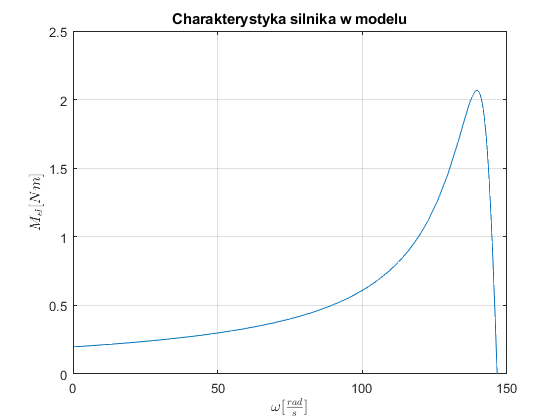

syms w m_el(w)
overload = 2.5;
f_main = 50; %Hz
n_sync = 1400;
w_sync = 2*pi*n_sync/60;
n_nom = n_sync * 0.99; %RPM
w_nom = 2*pi*n_nom/60; %s^-1
P_nom = 120; %W
M_nom = P_nom/w_nom;
S_nom = (n_sync-n_nom)/n_sync;
S_stall = S_nom*(overload+sqrt((overload^2)-1));
n_stall = n_sync-S_stall*n_sync;
w_stall = 2*pi*n_stall/60;
M_stall = overload*M_nom;

m_el(w) =(2.*M_stall.*(w_sync-w_stall).*(w_sync-w))/((w_sync-w_stall).^2+(w_sync-w).^2);

fplot(m_el(w));
axis([0, 150, 0, 2.5]); title('Charakterystyka silnika w modelu');
xlabel('$\omega[\frac{rad}{s}]$','Interpreter','latex');
ylabel ('$M_{el}[Nm]$','Interpreter','latex');
grid on;

%Rownania ruchu samego przenosnika

ddL_dqdoti_dt = [ddL_dVx_dt; ddL_dVy_dt; ddL_domegaa_dt; ddL_domegaf1_dt; ddL_domegaf2_dt];
dL_dqi = [dL_dx; dL_dy; dL_da; dL_df1; dL_df2];
dD_dqdoti = [dD_dVx; dD_dVy; dD_domegaa; dD_domegaf1; dD_domegaf2];
Qi = [0; 0; m_el(f1)-m_el(f2); m_el(f1); m_el(f2)];

eqns = [ddL_dqdoti_dt - dL_dqi + dD_dqdoti == Qi]

cond = [x(0)==0, y(0)==0, a(0)==0, f1(0)==0, f2(0)==1,...
    dx(0)==0, dy(0)==0, da(0)==0, df1(0)==0, df2(0)==0,...
    ddx(0)==0, ddy(0)==0, dda(0)==0, ddf1(0)==0, ddf2(0)==0]

$$cond = \left(\begin{array}{ccccccccccccccc} x\left(0\right)=0 & y\left(0\right)=0 & a\left(0\right)=0 & f_{1}\left(0\right)=0 & f_{2}\left(0\right)=1 & \left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)|}_{t=0}\right)=0 & \left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)=0 & \left({\left(\frac{\partial }{\partial t}a\left(t\right)\right)|}_{t=0}\right)=0 & \left({\left(\frac{\partial }{\partial t}f_{1}\left(t\right)\right)|}_{t=0}\right)=0 & \left({\left(\frac{\partial }{\partial t}f_{2}\left(t\right)\right)|}_{t=0}\right)=0 & \left({\left(\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)\right)|}_{t=0}\right)=0 & \left({\left(\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)\right)|}_{t=0}\right)=0 & \left({\left(\frac{\partial^{2}}{\partial t^{2}}a\left(t\right)\right)|}_{t=0}\right)=0 & \left({\left(\frac{\partial^{2}}{\partial t^{2}}f_{1}\left(t\right)\right)|}_{t=0}\right)=0 & \left({\left(\frac{\partial^{2}}{\partial t^{2}}f_{2}\left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$


solution = dsolve(eqns,cond)

 
solution =
 
[ empty sym ]
 
